cd

/Users/ishaanpanda/Desktop/Northeastern University/Financial Math/Matlab



% check working directory
cd '/Users/ishaanpanda/Desktop/Northeastern University/Financial Math/Matlab'
% change working directory to where the data set is saved
who


Your variables are:

INFL                  RSQUARED              betahat               ybar                  
LinearRegressiondata  SSR                   data                  
M1                    SST                   e                     
M2                    X                     n                     
Month                 ans                   y                     



save Regression.mat
format short %long numeric data type formatting
load regression.mat
who


Your variables are:

INFL                  RSQUARED              betahat               ybar                  
LinearRegressiondata  SSR                   data                  
M1                    SST                   e                     
M2                    X                     n                     
Month                 ans                   y                     



whos %display basic information of the workspace available

  Name                        Size            Bytes  Class       Attributes

  INFL                      497x1              3976  double                
  LinearRegressiondata      499x4             17593  table                 
  M1                        497x1              3976  double                
  M2                        497x1              3976  double                
  Month                     499x1              3992  datetime              
  RSQUARED                    1x1                 8  double                
  SSR                         1x1                 8  double                
  SST                         1x1                 8  double                
  X                         497x2              7952  double                
  ans                         1x1                 8  double                
  betahat                     2x1                16  double                
  data                      497x3             11928  double                
  e        

n = length(INFL) %number of observations

n = 497

# Scatter Monthly Inflation against M1

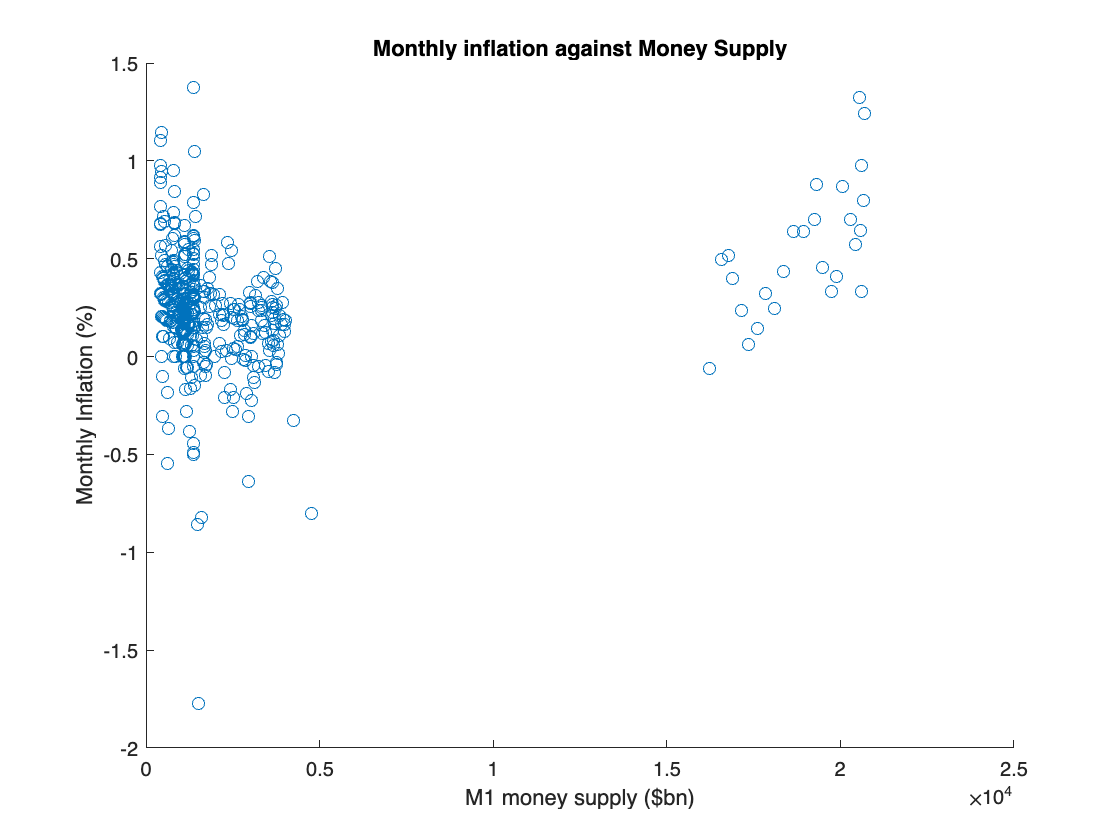

figure
scatter(M1,INFL)
xlabel('M1 money supply ($bn)')
ylabel('Monthly Inflation (%)')
title('Monthly inflation against Money Supply')

# Scatter Monthly Inflation against M2

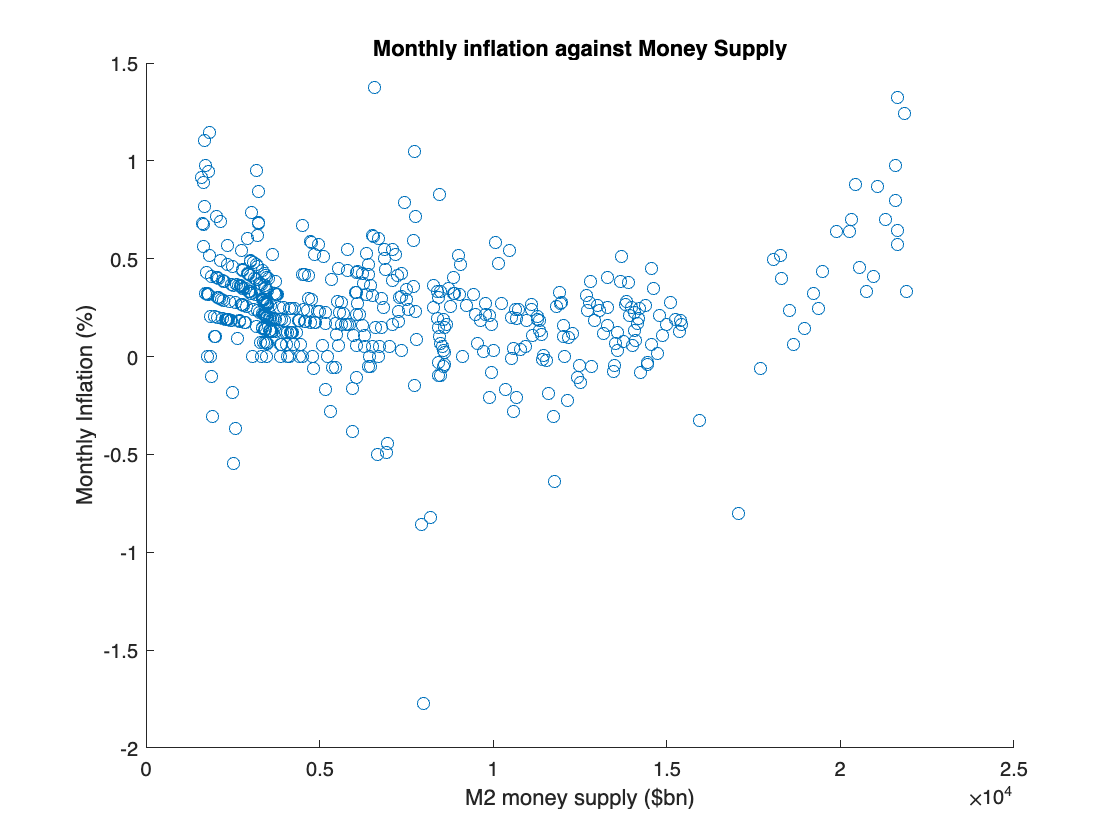

figure
scatter(M2,INFL)
xlabel('M2 money supply ($bn)')
ylabel('Monthly Inflation (%)')
title('Monthly inflation against Money Supply')

# Scatter Monthly Inflation against both M1 and M2

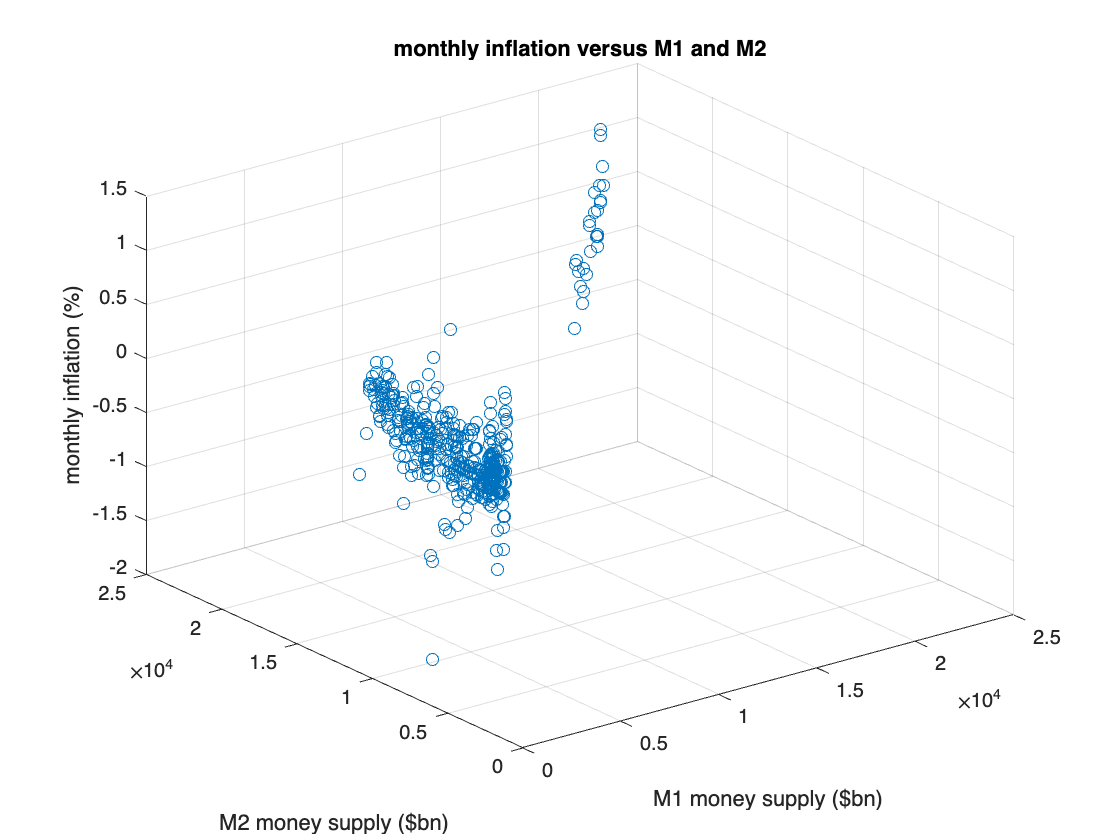

figure
  scatter3(M1,M2,INFL) % scatter inflation against M1 and M2.
  % label and title the figure.
  xlabel('M1 money supply ($bn)')
  ylabel('M2 money supply ($bn)')
  zlabel('monthly inflation (%)')
  title('monthly inflation versus M1 and M2')

# Calculate Descriptive Statistics for all variables

 data = [M1 M2 INFL] %put all variables into a single matrix

data = 1.0e+04 *

    0.0415    0.1608    0.0001
    0.0419    0.1629    0.0001
    0.0427    0.1666    0.0001
    0.0425    0.1655    0.0001
    0.0425    0.1664    0.0001
    0.0427    0.1685    0.0001
    0.0427    0.1693    0.0001
    0.0427    0.1706    0.0001
    0.0428    0.1725    0.0000
    0.0431    0.1739    0.0000


 mean(data)

ans = 1.0e+03 *

    2.4214    6.9865    0.0002


 median(data)

ans = 1.0e+03 *

    1.1710    5.3302    0.0002


 std(data)

ans = 1.0e+03 *

    4.0126    4.8869    0.0003


 mad(data) % mean absolute value of each column

ans = 1.0e+03 *

    2.0362    3.9406    0.0002


 min(data) % columnwise minimum

ans = 1.0e+03 *

    0.4148    1.6081   -0.0018


 max(data) % columnwise maximum

ans = 1.0e+04 *

    2.0699    2.1915    0.0001


X= [ones(n,1) M1] % 1st regressor is a constant; 2nd is M1 % ones(n) returns n by n matrix of all 1's $ ones(n,1) returns n by 1 matrix of 1's

X = 1.0e+04 *

    0.0001    0.0415
    0.0001    0.0419
    0.0001    0.0427
    0.0001    0.0425
    0.0001    0.0425
    0.0001    0.0427
    0.0001    0.0427
    0.0001    0.0427
    0.0001    0.0428
    0.0001    0.0431


% 1-D array is called a vector
% 2-D array is a matrix
ismatrix X

ans = logical
   1


y = INFL % Dependent variable is the inflation rate

y =     0.9174
    0.6818
    0.5643
    0.6734
    0.8919
    1.1050
    0.7650
    0.9761
    0.3222
    0.4283


format long
betahat=(X'*X)\(X'*y) % OLS explicit formula				

betahat =    0.211767910445710
   0.000014197186534


# **Calculate the coefficient of determination. **

format short % restore short numeric formatting.
  e=y-X*betahat % vector of regression residuals.

e =     0.6998
    0.4641
    0.3465
    0.4556
    0.6741
    0.8871
    0.5472
    0.7583
    0.1044
    0.2104


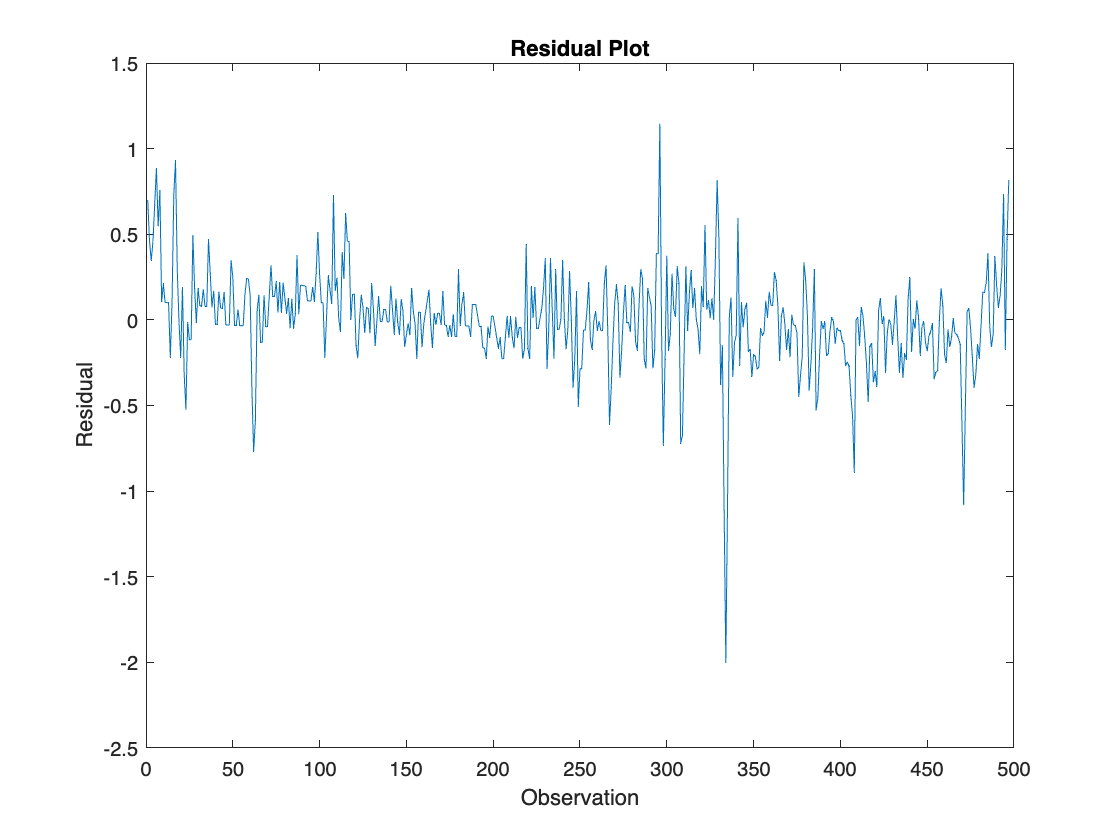

  % Plot Residuals
  figure
  plot (e)
  title('Residual Plot')
  xlabel('Observation')
  ylabel('Residual')

SSR=sum(e.^2) % residual sum of squares

SSR = 37.6423

 ybar=mean(y)    % mean of the dependent variable

ybar = 0.2461

 SST=sum((y-ybar).^2)    % total sum of squares

SST = 39.2519

RSQUARED=1-SSR/SST  % coefficient of determination

RSQUARED = 0.0410

sqrt(RSQUARED) % absolute value of the correlation coefficient

ans = 0.2025

corr(M1,INFL) % slope coefficient on M2 is negative					

ans = 0.2025

# **Regress inflation on M2 and a constant **

X=[ones(n,1) M2] % design matrix

X = 1.0e+04 *

    0.0001    0.1608
    0.0001    0.1629
    0.0001    0.1666
    0.0001    0.1655
    0.0001    0.1664
    0.0001    0.1685
    0.0001    0.1693
    0.0001    0.1706
    0.0001    0.1725
    0.0001    0.1739


format long % long numeric formatting.
  betahat=(X'*X)\(X'*y) % solution of the normal equations.

betahat =    0.256542089588222
  -0.000001488168024


# Calculate the Coeffecient of Determination

format short % restore short numeric format.
e=y-X*betahat % vector of residuals

e =     0.6633
    0.4277
    0.3103
    0.4193
    0.6378
    0.8509
    0.5110
    0.7221
    0.0683
    0.1743


SSR=sum(e.^2) % residual sum of squares

SSR = 39.2257

RSQUARED=1-SSR/SST % coefficient of determination

RSQUARED = 6.6833e-04

 sqrt(RSQUARED) % absolute value of the correlation coefficient

ans = 0.0259

 corr(M2,INFL) % slope coefficient on M2 is negative

ans = -0.0259

# Multiple linear regression : Regress Inflation on M1, M2 and a constant

 X=[ones(n,1) M1 M2] % regressors for multiple linear model

X = 1.0e+04 *

    0.0001    0.0415    0.1608
    0.0001    0.0419    0.1629
    0.0001    0.0427    0.1666
    0.0001    0.0425    0.1655
    0.0001    0.0425    0.1664
    0.0001    0.0427    0.1685
    0.0001    0.0427    0.1693
    0.0001    0.0427    0.1706
    0.0001    0.0428    0.1725
    0.0001    0.0431    0.1739


  format long
betahat=(X'*X)\(X'*y) % OLS model fit

betahat =    0.347440860487625
   0.000042494711361
  -0.000029226643802


format short
e=y-X*betahat % residual 

e =     0.5994
    0.3642
    0.2474
    0.3563
    0.5750
    0.7886
    0.4489
    0.6604
    0.0070
    0.1133


SSR=sum(e.^2) % residual sum of squares

SSR = 33.9188

RSQUARED=1-SSR/SST % coefficient of determination

RSQUARED = 0.1359

sqrt(RSQUARED) % multiple correlation coefficient

ans = 0.3686

corr(y,X*betahat) % correlation of y with the best linear predictor

ans = 0.3686